format long % 输出精度为long（16位数字）

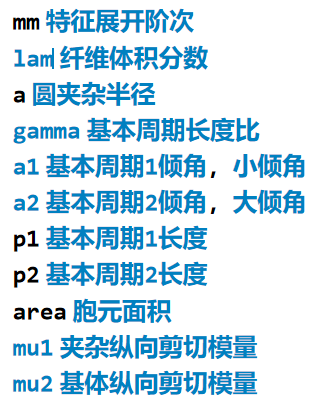

% 定义常量
mm = 1.0;
lam = 0.6;
a = 1e-9;
gamma = 1.0;
a1 = 0;
a2 = pi / 2;
p1 = sqrt(pi * a ^ 2 / (gamma * lam * sin(a2 - a1)));
p2 = p1 * gamma;
area = (pi * a ^ 2) / lam;

mu1 = 0.5;
mu2 = 1.0;
mu0 = 2e-10 * mu2;
eta = (mu2 - mu1 - mu0 / a) / (mu1 + mu2 + mu0 / a);

% 双周期分布的两个复周期
period = [
    p1*cos(a1)+p1*sin(a1)*1i, ...
    p2*cos(a2)+p2*sin(a2)*1i
    ]

period = 1.0e-08 *

  0.228822808215942 + 0.000000000000000i  0.000000000000000 + 0.228822808215942i


% 自然平行四边形单胞
corner = [
    (period(1)-period(2))/2, ...
    (period(1)+period(2))/2, ...
    -(period(1)-period(2))/2
    ]

corner = 1.0e-08 *

  0.114411404107971 - 0.114411404107971i  0.114411404107971 + 0.114411404107971i -0.114411404107971 + 0.114411404107971i



% 六边形单胞
% corner = [
%    (period(1)-2*period(2))/3, ...
%    (2*period(1)-period(2))/3, ...
%    (period(1)+period(2))/3, ... % ?!
%    -(period(1)-2*period(2))/2
%    ]

% 菱形单胞
% corner = [
%    period(1)/2, ...
%    (2*period(1)-period(2))/2, ...
%    -period(1)/2
%    ]

% (*行向错动矩形单胞*) d, h 没有给出，为未定义符号，跳过
% (*叠向错动矩形单胞*) d, h 没有给出，为未定义符号，跳过

`zeros`初始化为0。 `real` 为取实部、 `imag` 为取虚部，分别对应mma的Re、Im

delta_x = zeros(length(corner) - 1, 2);
for i = 1:length(corner)-1
    delta_x(i, :) = [real(corner(i) + corner(i + 1)), imag(corner(i) + corner(i + 1))];
end
delta_x

delta_x = 1.0e-08 *

   0.228822808215942                   0
                   0   0.228822808215942


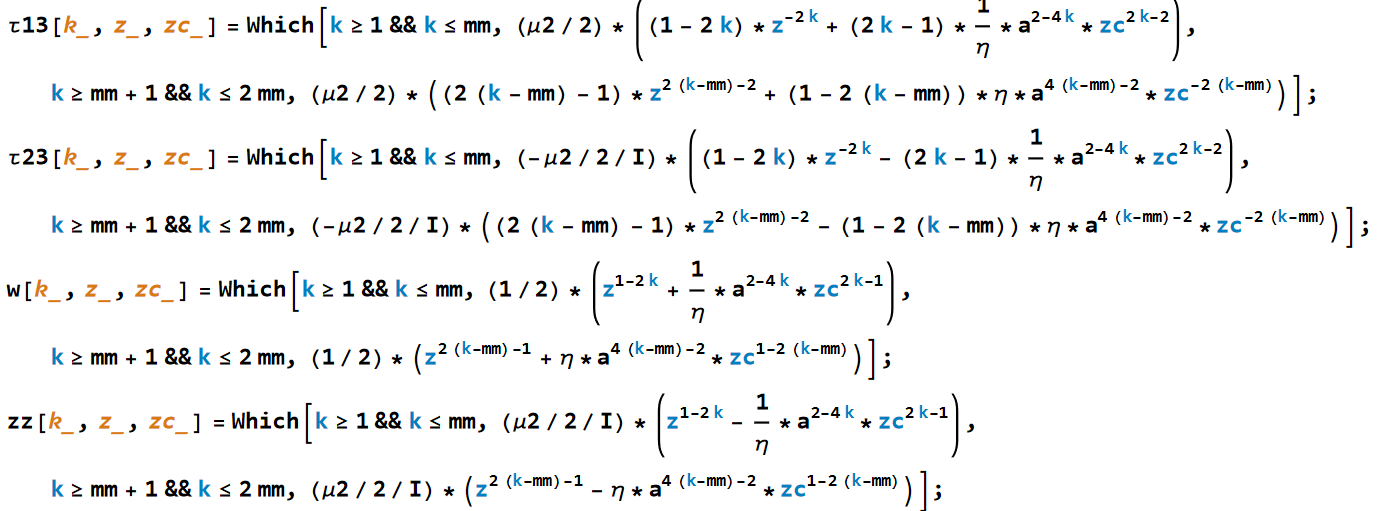

定义以上4个函数（使用逻辑值构造分段函数）

tau13 = @(k, z, zc) (k>=1&&k<=mm)*...
    (mu2./2).*((1-2.*k).*z^(-2.*k)+(2.*k-1)./eta.*(a.^(2-4.*k)).*zc.^(2.*k-2)) + ...
    (k>=mm+1&&k<=2*mm)*...
    (mu2./2).*((2.*(k-mm)-1).*z.^(2.*(k-mm)-2)+(1-2.*(k-mm)).*eta.*a.^(4.*(k-mm)-2).*zc.^(-2.*(k-mm)));
tau23 = @(k, z, zc) (k>=1&&k<=mm)*...
    (-mu2./2./(1i))*((1-2.*k).*z.^(-2.*k)-(2.*k-1)./eta.*(a.^(2-4.*k)).*zc.^(2.*k-2)) + ...
    (k>=mm+1&&k<=2*mm)*...
    (-mu2./2./(1i)).*((2.*(k-mm)-1).*z.^(2.*(k-mm)-2)-(1-2.*(k-mm)).*eta.*a.^(4.*(k-mm)-2).*zc.^(-2.*(k-mm)));
w = @(k, z, zc) (k>=1&&k<=mm)*...
    (1/2).*(z.^(1-2.*k) + 1./eta.*a.^(2-4.*k).*zc.^(2.*k-1)) + ...
    (k>=mm+1&&k<=2*mm)*...
    (1/2).*(z.^(2.*(k-mm)-1)+eta.*a.^(4.*(k-mm)-2).*zc.^(1-2.*(k-mm)));
zz = @(k, z, zc) (k>=1&&k<=mm)*...
    (mu2./2./(1i)).*(z.^(1-2.*k)-1./eta.*a.^(2-4.*k).*zc.^(2.*k-1)) + ...
    (k>=mm+1&&k<=2*mm)*...
    (mu2./2./(1i)).*(z.^(2.*(k-mm)-1)-eta.*a.^(4.*(k-mm)-2).*zc.^(1-2.*(k-mm)));

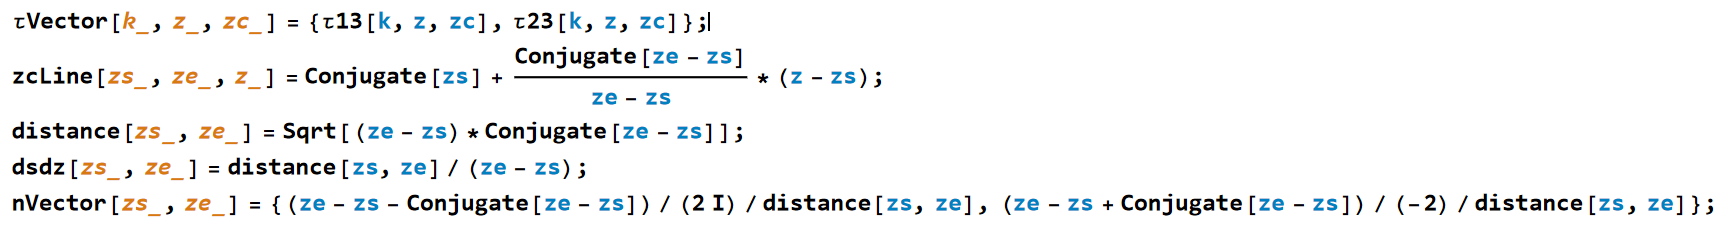

按顺序定义以上5个函数， `conj` 为取共轭

tauVec = @(k, z, zc) [tau13(k,z,zc), tau23(k,z,zc)];
zcLine = @(zs, ze, z) conj(zs) + conj(ze-zs)./(ze-zs).*(z-zs);
distance = @(zs, ze) sqrt((ze-zs).*conj(ze-zs));
dsdz = @(zs, ze) distance(zs,ze)./(ze-zs);
nVec = @(zs, ze) [(ze-zs-conj(ze-zs))./(2i)./distance(zs,ze),(ze-zs+conj(ze-zs))./(-2)./distance(zs,ze)];

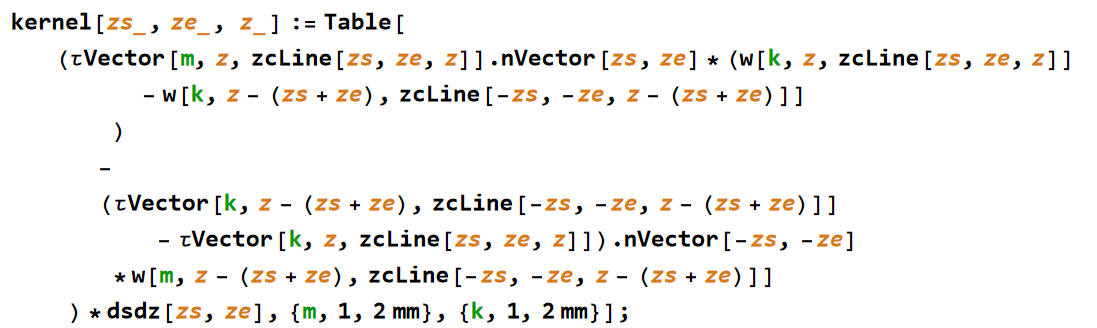

定义核函数 `kernel` ，Matlab中使用 `cell` 存储函数矩阵

kernel = cell(2*mm, 2*mm);
for k = 1:2*mm
    for m = 1:2*mm
        kernel{m, k} = @(zs,ze,z) ( ...
            (sum(tauVec(m,z,zcLine(zs,ze,z)).*nVec(zs,ze))).*( ...
                w(k,z,zcLine(zs,ze,z))-w(k,z-(zs+ze),zcLine(-zs,-ze,z-(zs+ze))) ...
            ) - ...
            sum((tauVec(k,z-(zs+ze),zcLine(-zs,-ze,z-(zs+ze)))-tauVec(k, z, zcLine(zs, ze, z))).*(nVec(-zs,-ze))) ...
            .*w(m,z-(zs+ze),zcLine(-zs,-ze,z-(zs+ze))) ...
       ).*dsdz(zs,ze);
    end
end

使用数值积分代替 `NIntegerate，计算量较小直接使用了矩形近似`

% boundint = @(m,k,zs,ze) integrate(@(t) kernel{m,k}(t.*(ze-zs),zs,ze),0,1);
zzSum = @(k,zs,ze) zz(k,ze,zcLine(zs,ze,ze))-zz(k,zs,zcLine(zs,ze,zs));

matrixC = zeros(2*mm, 2*mm);
N = 10000;
for m = 1:2*mm
    for k = m:2*mm
        sm = 0;
        for i = 1:length(corner)-1
            cxs = linspace(corner(i),corner(i+1),N); % 从corner(i)积到corner(i+1)
            h = cxs(2) - cxs(1); % 步长

            sm2 = 0;
            for cx = cxs
                sm2 = sm2 + kernel{m,k}(corner(i),corner(i+1),cx) * h;
            end
            sm2

            sm = sm + sm2;
        end
        sm
        disp("-------------------")
        matrixC(m,k) = sm;
    end
    matrixC(k,m) = matrixC(m,k);
end

sm2 =       4.154654487626245e+19 - 3.546250000000000e+02i


sm2 =      -4.154654487626245e+19 + 3.546250000000000e+02i


sm =      0


-------------------


sm2 =   7.955587467854107 + 0.000000000000000i


sm2 =   7.955587467854107 + 0.000000000000000i


sm =  15.911174935708214 + 0.000000000000000i


-------------------


sm2 =       1.293837037669075e-18 - 3.253180615900681e-36i


sm2 =      -1.293837037669075e-18 + 3.253180615900681e-36i


sm =      0


-------------------



matrixC

matrixC =   0.000000000000000 + 0.000000000000000i 15.911174935708214 + 0.000000000000000i
 15.911174935708214 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i


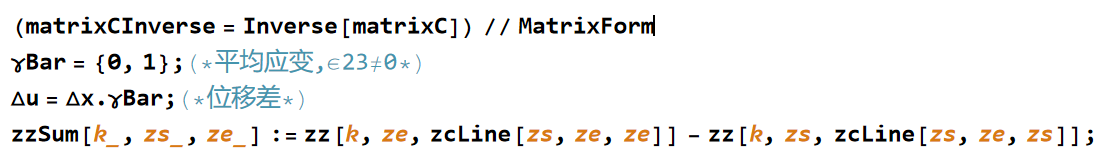

Cinv = inv(matrixC)

Cinv =   0.000000000000000 + 0.000000000000000i  0.062848909903930 - 0.000000000000000i
  0.062848909903930 - 0.000000000000000i  0.000000000000000 + 0.000000000000000i



% 平均应变, ε23 != 0
gammaBar = [0,1];
% 位移差
delta_u = delta_x*gammaBar';

zzSum = @(k,zs,ze) zz(k,ze,zcLine(zs,ze,ze))-zz(k,zs,zcLine(zs,ze,zs));

vecB = zeros(2*mm,1);
for m = 1:2*mm
    sm = 0;
    for j = 1:length(corner)-1
        sm = sm + delta_u(j)*zzSum(m,corner(j),corner(j+1));
    end
    vecB(m) = sm;
end
vecB

vecB =   0.000000000000000 -13.835298641951798i
  0.000000000000000 + 0.000000000000000i



vecA = matrixC \ vecB % A = C^{-1} B

vecA =   0.000000000000000 + 0.000000000000000i
 -0.000000000000000 - 0.869533437841998i


zzSide = zeros(1, length(corner)-1);
for i = 1:length(corner)-1 % table 部分
    sm = 0;
    for k = 1:2*mm % sum 部分
        sm = sm + vecA(k)*zzSum(k,corner(i),corner(i+1));
    end
    zzSide(i) = sm;
end
zzSide

zzSide = 1.0e-08 *

  0.000000000000000 - 0.000000000000000i  0.185557214008975 - 0.000000000000000i


tau13Bar = real(sum(zzSide(1:length(corner)-1) .* delta_x(1:length(corner)-1, 1)')) / area

tau13Bar =      0


tau23Bar = real(sum(zzSide(1:length(corner)-1) .* delta_x(1:length(corner)-1, 2)')) / area

tau23Bar =    0.810920971802178
